# ASEN 2004

Tristan Workman, ID: 109326637, last modified 

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


X =          0         0    0.2500         0         0         0    0.9253    0.0053    0.0012
    0.0000         0    0.2500    0.0001         0    0.0000    0.9253    0.0053    0.0012
    0.0000         0    0.2500    0.0001         0    0.0001    0.9253    0.0053    0.0012
    0.0000         0    0.2500    0.0002         0    0.0001    0.9253    0.0053    0.0012
    0.0000         0    0.2500    0.0002         0    0.0002    0.9253    0.0053    0.0012
    0.0000         0    0.2500    0.0005         0    0.0004    0.9253    0.0053    0.0012
    0.0000         0    0.2500    0.0007         0    0.0006    0.9253    0.0053    0.0012
    0.0000         0    0.2500    0.0010         0    0.0009    0.9253    0.0053    0.0012
    0.0000         0    0.2500    0.0012         0    0.0011    0.9253    0.0053    0.0012
    0.0000         0    0.2500    0.0025         0    0.0023    0.9252    0.0053    0.0012


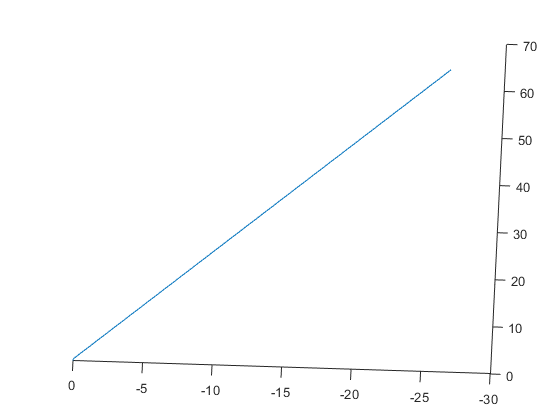

% Using thermodynamic and aerodynamic relations, and equations of motion, determine 
% the trajectory of a bottle rocket with specified initial properties

% wind (+/- 11.25 degrees from SW), (+/- .1 m/s wind speed)
% mass, launchpad angle (std 1 degree)
% bottle diameter (+/- .1 cm), bottle throat (+/- .1 cm) pressure

% Assumptions
% Steady, uniform 1D flow, only 2D required, Ideal weather + Gas,
% Compressible within the bottle (two densities)

g = 9.81; % [m/s^2]
C_discharge = 0.8; % discharge coefficient
rho_amb = 0.961; % kg/m^3 ambient air density
Vol_bottle = 0.002; % m^3 volume of empty bottle
P_amb = 83426.56; % Pa atmospheric pressure
gamma = 1.4; % ratio of specific heats for air
rho_water = 1000; % kg/m^3 density of water
D_throat = 2.1; % cm diameter of the throat
D_bottle = 10.5; % cm diameter of bottle
R = 287; % J/kgK gas constant of air
M_bottle = 0.16; % kg mass of empty 2 litre bottle with cones and fins
T_airI = 290.372; % K initial temperature of air
v0 = 0.0; % m/s initial velocity of rocket
x0 = 0.0; % m initial horizontal displacement
y0 = 0.0; % m initial lateral displacement
z0 = 0.25; % m initial vertical displacement
l_s = 0.5; % m length of test stand
tspan = [0 5]; % integration time
windspeed = 3.57632; % m/s
windangle = deg2rad(45); % radians

A_t = pi * (D_throat/200)^2; % m^2 area of throat
A_B = pi * (D_bottle/200)^2; % m^2 cross sectional area of bottle

% After meeting the verification requirements, I begin to try test cases
% make 1 true and all others false to see associated graph 
% Verification case on by default
verification = true;
testcase = false;
pressureChange = false;
volChange = false;
dragChange = false;
thetaChange = false;
if (verification == true)
    P_gage = 275790; % initial gage pressure of air in bottle
    Vol_waterI = .76/rho_water; % m^3 initial volume of water inside bottle
    C_drag = 0.30; % drag coefficient
    theta = deg2rad(45); % radians initial angle of rocket
    
    % determining rocket mass
    P_airI = (P_gage + P_amb);
    rho_air_bottleI = P_airI ./ (R .* T_airI);
    M_waterI = (Vol_waterI .* rho_water); 
    Vol_airI = (Vol_bottle - Vol_waterI);
    M_airI = (P_airI .* Vol_airI)./(R .* T_airI);
    RMI = M_bottle + M_waterI + M_airI;
    
    X0 = [x0,y0,z0,v0,v0,v0,RMI,M_airI,Vol_airI];
    
    opt = odeset('Events', @stopEvent);
    [t, X] = ode45(@(t,x) odeFun(t,x,g,C_discharge,rho_amb,Vol_bottle,P_amb,gamma,rho_water,A_t,R,C_drag,T_airI,theta,l_s,Vol_airI,P_airI,M_airI,A_B,x0,z0,y0,windspeed,windangle), tspan, X0, opt)
    plot3(X(:,1),X(:,2),X(:,3))
%     Force_t = thrust(X,C_discharge,A_t,P_airI,Vol_airI,gamma,P_amb,Vol_bottle,M_airI,R);
%     dist = max(X(:,1))
%     height = max(X(:,2))
elseif (testcase == true)
    P_gage = 344738 + 80000; % initial gage pressure of air in bottle
    Vol_waterI = 0.0008; % m^3 initial volume of water inside bottle
    C_drag = 0.5; % drag coefficient
    theta = deg2rad(40); % radians initial angle of rocket
    
    % determining rocket mass
    P_airI = (P_gage + P_amb);
    rho_air_bottleI = P_airI ./ (R .* T_airI);
    M_waterI = (Vol_waterI .* rho_water); 
    Vol_airI = (Vol_bottle - Vol_waterI);
    M_airI = (P_airI .* Vol_airI)./(R .* T_airI);
    RMI = M_bottle + M_waterI + M_airI;
    
    opt = odeset('Events', @stopEvent);
    [t, X] = ode45(@(t,x) odeFun(t,x,g,C_discharge,rho_amb,Vol_bottle,P_amb,gamma,rho_water,A_t,R,C_drag,T_airI,theta,l_s,Vol_airI,P_airI,M_airI,A_B,x0,z0,y0,windspeed,windangle), tspan, X0, opt);
    Force_t = thrust(X,C_discharge,A_t,P_airI,Vol_airI,gamma,P_amb,Vol_bottle,M_airI,R);
    dist = max(X(:,1))
    height = max(X(:,2))
end


% X = [
%   x - x position
%   z - z position
%   Vx - x component of velocity
%   Vz - z component of velocity
%   RM - rocket mass
%   AM - mass of air
%   AV - volume of air
% ]

% Xdot = [
%   vx - velocity in x
%   vz - velocity in z
%   ax - acceleration in x
%   az - acceleration in z
%   RMdot - change in rocket mass
%   AMdot - change in mass of air
%   AVdot - change in volume of air
% ]

% if (verification == true || testcase == true)
%     % Finding where the phases lie on the trajectory graph
%     [~,ind1] = min(abs(t-0.204625));
%     [~,ind2] = min(abs(t-0.2544));
%     X(ind1,1);
%     X(ind2,1);
%     
%     figure(1)
%     plot(X(:,1),X(:,2),"LineWidth",1.5)
%     hold on
%     title("Bottle Rocket Trajectory")
%     set(0,'defaultTextInterpreter','latex')
%     set(gca,'FontSize',11)
%     % xline(X(ind1,1),"Linewidth",1.5)
%     % xline(X(ind2,1),"Linewidth",1.5)
%     if (verification == true)
%         ylim([0 20]) % for verification case
%     elseif (testcase == true)
%         ylim([0 25])
%     end
%     ylabel("Height [m]")
%     xlabel("Distance [m]")
%     grid on
%     hold off 
%     
%     figure(2)
%     plot(t,X(:,4),"LineWidth",1.5)
%     hold on
%     title("Bottle Rocket Z-Velocity")
%     set(0,'defaultTextInterpreter','latex')
%     set(gca,'FontSize',11)
%     ylabel("Z-Velocity [m/s]")
%     xlabel("Time [s]")
%     grid on
%     hold off
%     
%     figure(3)
%     plot(t,X(:,3),"LineWidth",1.5)
%     hold on
%     title("Bottle Rocket X-Velocity")
%     set(0,'defaultTextInterpreter','latex')
%     set(gca,'FontSize',11)
%     ylabel("X-Velocity [m/s]")
%     xlabel("Time [s]")
%     grid on
%     hold off
%     
%     figure(4)
%     plot(t((t(:,1) < .25),1),X((t(:,1) < 0.25),7),"LineWidth",1.5)
%     hold on
%     title("Bottle Rocket Air Volume Evolution")
%     set(0,'defaultTextInterpreter','latex')
%     set(gca,'FontSize',11)
%     ylabel("Air Volume in Bottle Rocket [m$^3$]")
%     xlabel("Time [s]")
%     ylim([1 * 10^-3, 2 * 10^-3])
%     grid on
%     hold off
%     
%     figure(5)
%     plot(t((t(:,1) < 1),1),Force_t(1,(t(:,1) < 1)),"LineWidth",1.5)
%     hold on
%     if (verification == true)
%         xline(0.204625,"Linewidth",1.5)
%         xline(0.2544,"Linewidth",1.5)
%     elseif (testcase == true)
%         xline(0.152,"Linewidth",1.5)
%         xline(0.197,"Linewidth",1.5)
%     end
%     title("Thrust vs Time for Bottle Rocket")
%     set(0,'defaultTextInterpreter','latex')
%     set(gca,'FontSize',11)
%     ylabel("Thrust [N]")
%     xlabel("Time [s]")
%     xlim([0 .45])
%     grid on
%     hold off
% end

## Function propogation

function [value, isterminal, direction] = stopEvent(t,X)
    value = (X(3) <= 0);
    isterminal = 1;
    direction = 0;
end
function dx = odeFun(t,x,g,C_discharge,rho_amb,Vol_bottle,P_amb,gamma,rho_water,A_t,R,C_drag,T_airI,theta,l_s,Vol_airI,P_airI,M_airI,A_B,x0,z0,y0,windspeed,windangle)
    % must split into three parts, as there are three sections of flight
    % Part 1 is powered (water exhaust), so drag + thrust(water) + gravity
    % Part 2 is also powered (air exhaust), so drag + thrust(air) + gravity
    % Part 3 is unpowered, so just drag + gravity
    xpos = x(1);
    ypos = x(2);
    zpos = x(3);
    Vx = x(4);
    Vy = x(5);
    Vz = x(6);
    RM = x(7);
    AM = x(8);
    AV = x(9);
    
    % velocity vector is just combination of components
    V = sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
    
    % Part 1
    if (AV < Vol_bottle) 
        % calculating change in volume of air over time
        AVdot = C_discharge .* A_t .* sqrt((2./rho_water) .* ((P_airI .* (Vol_airI./AV).^gamma) - P_amb));
        % calculating current pressure based on volume
        P_air = P_airI .* (Vol_airI./AV).^gamma;
        % calculating change in mass of the rocket over time
        RMdot = -C_discharge .* A_t .* sqrt(2 .* rho_water .* (P_air - P_amb));
        % with P_air we can now calculate the force from thrust
        F_t = 2 .* C_discharge .* A_t .* (P_air - P_amb);
        % change in air mass is zero because of phase of flight
        AMdot = 0;
    else
        % set pressure and temperature to fixed values after all water is
        % expelled (AV >= Vol_bottle) && (P_air > P_amb)
        % calculating pressure at end of part 1
        P_air_end = P_airI .* (Vol_airI./Vol_bottle).^gamma;
        % calculating temperature at the end of part 1
        T_air_end = T_airI .* (Vol_airI./Vol_bottle).^(gamma-1);
        % Air pressure now changes (no water left in the bottle)
        % calculating new pressure
        P_air = P_air_end .* (AM./M_airI).^gamma;
    end
    
    % Part 2
    if (AV >= Vol_bottle) && (P_air > P_amb)
        % Calculating air density/temperature
        rho_air_bottle = AM./Vol_bottle;
        T_air = P_air ./ (rho_air_bottle .* R);
        % determining whether choked flow, need critical pressure
        P_crit = P_air .* (2 ./ (gamma + 1)).^(gamma./(gamma-1));
        if (P_crit > P_amb)
            % flow is choked, determine exit velocity
            % need temperature at exit
            T_exit = T_air .* (2./(gamma+1));
            % calculating exit velocity
            V_exit = sqrt(gamma .* R .* T_exit);
            % air pressure at exit is just critical pressure
            P_exit = P_crit;
            % calculating air density at exit
            rho_air_exit = P_exit ./ (R .* T_exit);
        elseif (P_crit < P_amb)
            % solve for exit mach speed through pressure relation
            Mach_exit = sqrt((((P_air./P_amb).^((gamma-1)./gamma))-1)./((gamma-1)./2));
            % calculating temperature of air at exit
            T_exit = T_air ./ (1 + (((gamma-1)./2) .* (Mach_exit.^2)));
            % air pressure at exit is just ambient pressure
            P_exit = P_amb;
            % calculating density at exit
            rho_air_exit = P_exit ./ (R .* T_exit);
            % now we can calculate exit velocity
            V_exit = Mach_exit .* sqrt(gamma .* R .* T_exit);
        end
        % thrust, air mass, and rocket mass change by the same functions
        % calculating change in air mass
        AMdot = -C_drag .* rho_air_exit .* A_t .* V_exit;
        % calculating thrust
        F_t = (-AMdot) .* V_exit + ((P_amb - P_exit) .* A_t);
        % Calculating change in rocket mass (same as change in air mass)
        RMdot = AMdot;
        % Air volume is unchanging during this phase
        AVdot = 0;
    end
    
    % Part 3
    if (AV >= Vol_bottle) && (P_air <= P_amb)
        % no water or air exhaust thrust
        F_t = 0;
        AVdot = 0;
        % Change in air mass is zero, as pressure has equalized
        AMdot = 0;
        % change in mass is zero (again no exhaust and pressure equalized)
        RMdot = 0;
    end
    
%     if (zpos < 5)
%         
%     elseif (zpos <= 22 && zpos > 3)
%         
%         windx = (zpos/22 * windspeed) * sin(abs(deg2rad(40) - windangle));
%         windy = (zpos/22 * windspeed) * cos(abs(deg2rad(40) - windangle));
%         
%         Vx = Vx - windx;
%         Vy = Vy - windy;
%         
%         hx = (Vx)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
%         hz = (Vz)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
%         hy = (Vy)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
%     else
%         
%     end
    
    % initial heading is determined by test stand
    % so we have to check whether its cleared the stand yet (using trig)
    % if (sqrt(((zpos - z0)^2) + ((xpos - x0)^2)) <= l_s)
    if (xpos < (l_s .* cos(theta) + x0) && zpos < (l_s .* sin(theta) + z0))
        % once it has cleared the stand, heading is determined by velocity
        % components
        hx = cos(theta);
        hz = sin(theta);
        hy = 0;
    else
        windx = windspeed * sin(abs(deg2rad(40) - windangle));
        windy = windspeed * cos(abs(deg2rad(40) - windangle));
        
        Vx = Vx - windx;
        Vy = Vy - windy;
        hx = (Vx)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
        hz = (Vz)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
        hy = (Vy)./sqrt((Vx.^2) + (Vz.^2) + (Vy.^2));
    end
    
    
    % Since drag force is a simple function of area and velocity, it can
    % be calculated outside of the individual parts
    
    % Calculating drag:
    F_d = (1/2) .* rho_amb .* V^2 .* C_drag .* A_B;
    
    
    % Now, we have all forces responsible for motion 
    % We can now determine the acceleration components which govern
    % trajectory:
    accelX = ((F_t .* hx) - (F_d .* hx)) ./ RM; 
    accelZ = ((F_t .* hz) - (F_d .* hz) - (RM .* g)) ./ RM;
    accelY = ((F_t .* hy) - (F_d .* hy)) ./ RM;
    
    % final outputs for state vector
    dx = [Vx; Vy; Vz; accelX; accelY; accelZ; RMdot; AMdot; AVdot];
end
function T = thrust(X,C_discharge,A_t,P_airI,Vol_airI,gamma,P_amb,Vol_bottle,M_airI,R)
    % use state matrix data (X) to extract force of thrust, so it can be graphed and verified
    for k = 1:size(X,1)
        % thrust equations require AM and AV
        AM = X(k,6); % air mass
        AV = X(k,7); % air volume
        % rest of code is copied from ODE function
        % Part 1
        if (AV < Vol_bottle) 
            % calculating current pressure based on volume
            P_air = P_airI .* (Vol_airI./AV).^gamma;
            % with P_air we can now calculate the force from thrust
            F_t = 2 .* C_discharge .* A_t .* (P_air - P_amb);
        else
            % set pressure and temperature to fixed values after all water is
            % expelled (AV >= Vol_bottle) && (P_air > P_amb)
            % calculating pressure at end of part 1
            P_air_end = P_airI .* (Vol_airI./Vol_bottle).^gamma;
            % Air pressure now changes (no water left in the bottle)
            % calculating new pressure
            P_air = P_air_end .* (AM./M_airI).^gamma;
        end
        
        % Part 2
        if (AV >= Vol_bottle) && (P_air > P_amb)
            % Calculating air density/temperature
            rho_air_bottle = AM./Vol_bottle;
            T_air = P_air ./ (rho_air_bottle .* R);
            % determining whether choked flow, need critical pressure
            P_crit = P_air .* (2 ./ (gamma + 1)).^(gamma./(gamma-1));
            if (P_crit > P_amb)
                % flow is choked, determine exit velocity
                % need temperature at exit
                T_exit = T_air .* (2./(gamma+1));
                % calculating exit velocity
                V_exit = sqrt(gamma .* R .* T_exit);
                % air pressure at exit is just critical pressure
                P_exit = P_crit;
                % calculating air density at exit
                rho_air_exit = P_exit ./ (R .* T_exit);
            elseif (P_crit < P_amb)
                % solve for exit mach speed through pressure relation
                Mach_exit = sqrt((((P_air./P_amb).^((gamma-1)./gamma))-1)./((gamma-1)./2));
                % calculating temperature of air at exit
                T_exit = T_air ./ (1 + (((gamma-1)./2) .* (Mach_exit.^2)));
                % air pressure at exit is just ambient pressure
                P_exit = P_amb;
                % calculating density at exit
                rho_air_exit = P_exit ./ (R .* T_exit);
                % now we can calculate exit velocity
                V_exit = Mach_exit .* sqrt(gamma .* R .* T_exit);
            end
            % thrust, air mass, and rocket mass change by the same functions
            % calculating thrust
            F_t = (C_discharge .* rho_air_exit .* A_t .* V_exit) .* V_exit + ((P_amb - P_exit) .* A_t);
        end
    
        % Part 3
        if (AV >= Vol_bottle) && (P_air < P_amb)
            % no water or air exhaust thrust
            F_t = 0;
        end
        T(k) = F_t;
    end
end